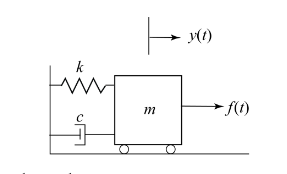

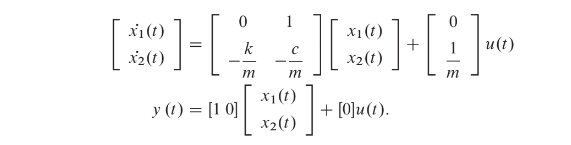

k = 1; % defining the value of K
m = 2; % defining the value of m
c = 3; % defining the value of c


A = [ 0 1; -k/m -c/m];
B = [0; 1/m];
C = [1 0];
D = [0];

% Creates an object sys representing the continuous-time state of space model
sys = ss(A,B,C,D)

sys =
 
  A = 
         x1    x2
   x1     0     1
   x2  -0.5  -1.5
 
  B = 
        u1
   x1    0
   x2  0.5
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



% Recovers the matrices for a sys object
% A, B, C, D = ssdata(sys) 
size(sys)

State-space model with 1 outputs, 1 inputs, and 2 states.


order(sys)

ans = 2

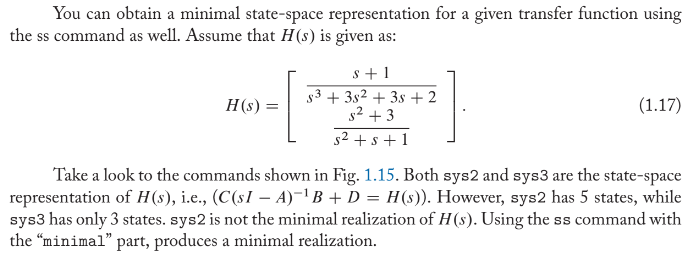

% Obtaining the minimal state-space realization of a system.

H = [tf([1 1], [1 3 3 2]); tf([1 0 3], [1 1 1])]

H =
 
  From input to output...
               s + 1
   1:  ---------------------
       s^3 + 3 s^2 + 3 s + 2
 
         s^2 + 3
   2:  -----------
       s^2 + s + 1
 
Continuous-time transfer function.



sys2 = ss(H);
size(sys2)

State-space model with 2 outputs, 1 inputs, and 5 states.



sys3 = ss(H, 'minimal');
size(sys3)

State-space model with 2 outputs, 1 inputs, and 3 states.


The transfer function of both systems are the same.

tf(sys2)

ans =
 
  From input to output...
               s + 1
   1:  ---------------------
       s^3 + 3 s^2 + 3 s + 2
 
         s^2 + 3
   2:  -----------
       s^2 + s + 1
 
Continuous-time transfer function.



tf(sys3)

ans =
 
  From input to output...
               s + 1
   1:  ---------------------
       s^3 + 3 s^2 + 3 s + 2
 
       s^3 + 2 s^2 + 3 s + 6
   2:  ---------------------
       s^3 + 3 s^2 + 3 s + 2
 
Continuous-time transfer function.



pole(sys)

ans =    -0.5000
   -1.0000


zero(sys)


ans =

  0×1 empty double column vector



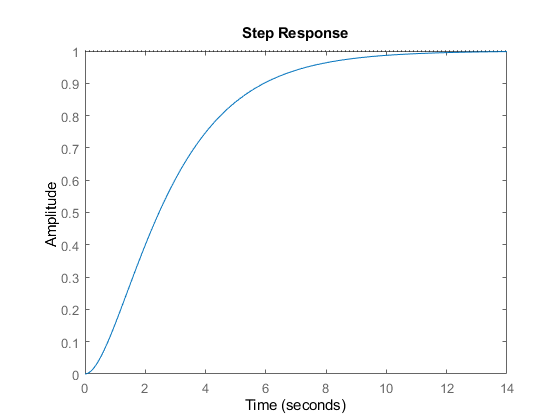

% The step response of system sys.
step(sys)

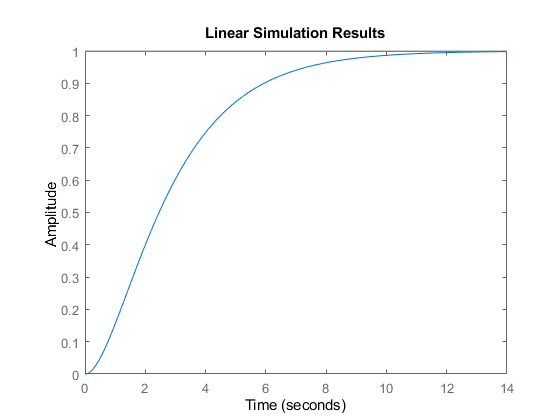

% Simulating the system with a sinusoidal input and an initial condition.
% MATLAB has a powerful command named lsim for simulating the linear systems with
% arbitrary inputs. The lsim command takes the time vector and value of system input for each
% time instant.

t = 0:0.01:14;
u = ones(size(t));
lsim(sys, u, t)

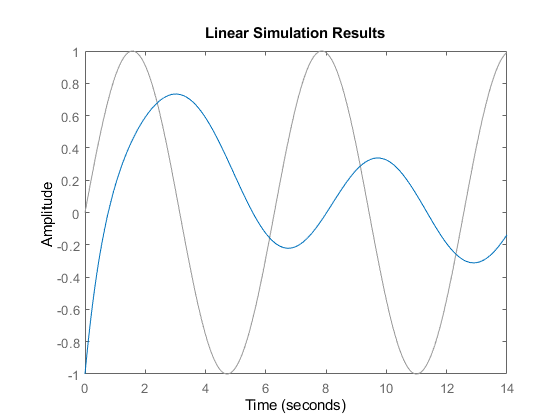


t = 0:0.01:14;
u = sin(t);
lsim(sys, u, t, [-1; 2])